l = qd_layout;
params.fs = 1000;
params.no_UE = 30;
params.P_local = 0.8;
params.local_radius = 150;
params.tot_time = 6;
params.P_turn = 0.1;
max_xy = 500;

l.no_tx = 2;
l.tx_track(1).initial_position = [0; 0; 25];
l.tx_track(2).initial_position = [200; 150; 25];

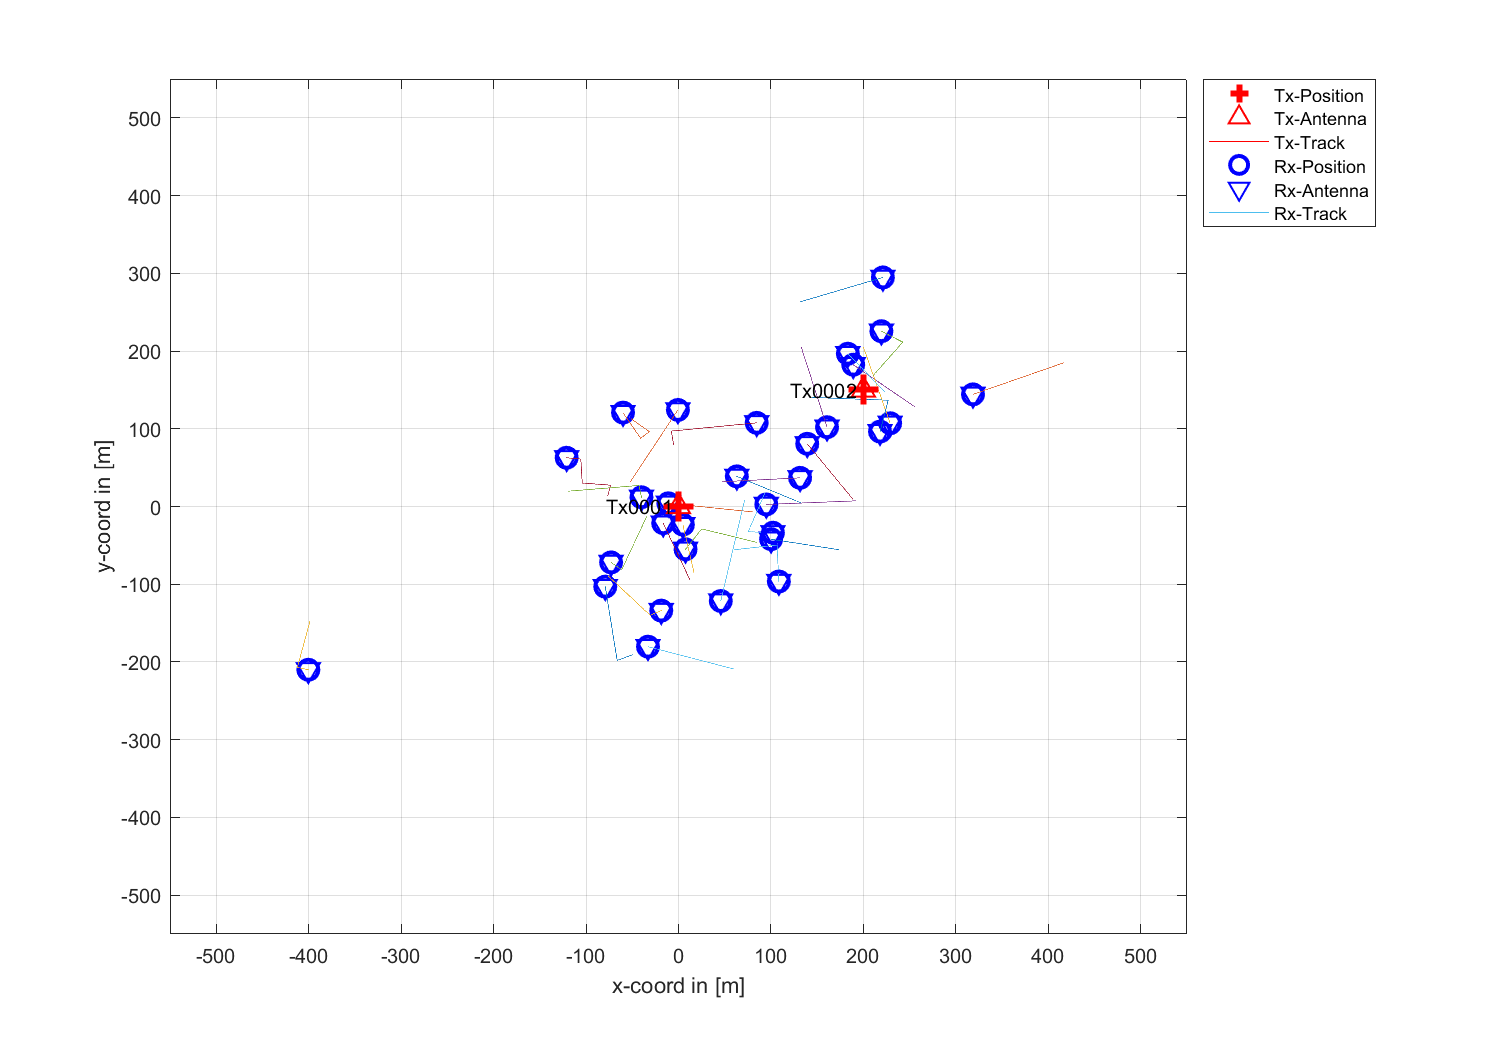

l.no_rx = params.no_UE;
per_BS_UE = floor(l.no_rx / l.no_tx);

for k=1:l.no_tx
    [locs, vels, speeds, no_segments, t_unit] = RandomizeUE(per_BS_UE, params.P_local, params.local_radius, params.tot_time, l.tx_track(k).initial_position(1), l.tx_track(k).initial_position(2), max_xy, params.P_turn);
    
    for i=1:per_BS_UE
    t = qd_track('linear', t_unit*speeds(i), atan2(vels(i, 2, 1), vels(i, 1, 1)));
        t.initial_position = locs(i, :)';
        t.name = ['Rx',sprintf('%06.0f',i+(k-1)*per_BS_UE)];
%         t.set_speed(speeds(i));
        t.movement_profile = [0, t_unit; 0, speeds(i)*t_unit];
        [~, t] = interpolate(t.copy, 'time', 1/params.fs);
        
        for j=2:no_segments
            tmp = qd_track('linear', t_unit*speeds(i), atan2(vels(i, 2, j), vels(i, 1, j)));
            tmp.set_speed(speeds(i));
            tmp.interpolate('time', 1/params.fs);
            
            t.positions = [t.positions,... 
                [t.positions(1, end) + tmp.positions(1, 2:end);
                 t.positions(2, end) + tmp.positions(2, 2:end);
                 1.5*ones(1, numel(tmp.positions(1, 2:end)))]];
                 
        end
        l.rx_track(i+(k-1)*per_BS_UE) = t.copy();
        l.rx_track(i+(k-1)*per_BS_UE).positions = l.rx_track(i+(k-1)*per_BS_UE).positions(:, 1:end-1); % remove last unnecessary point
    end
end
l.visualize;

p = l.init_builder();
p.gen_parameters();
c = get_channels(p);